# Actividad 4.1 Senoidal

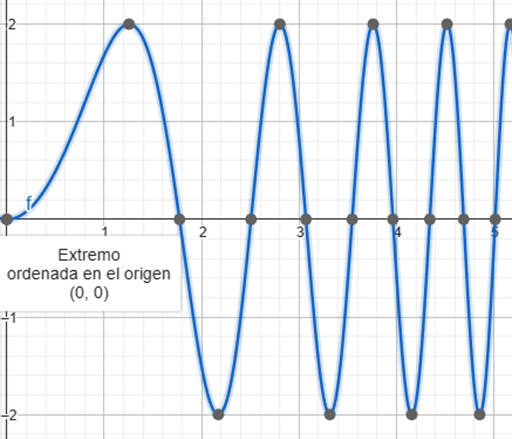

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Para esta parte se fue modificando el tiempo en base a el numero de los vectores que se iba aumentando, hasta alcanzar uno optimo para la simulación, en este caso se cumple mas o menos la parte de la senoidal, debido a que es muy dificil lograrlo de manera adecuada con robot y mas, sin embargo se puede mejorar acortando el tiempo de muestreo pasandolo a .1 y ocupando lo que es vectores mas largos para tomar las vueltas mas cerradas o en este caso mas suaves para que así se cumpla con lo especificado. 

tf = 18;             % Tiempo de simulacion en segundos (s) 8 circulo 
ts = 0.2;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

En este caso la simulación inicia en el origen. 

x1(1) = 0;    % Posicion inicial eje x   
y1(1) = 0;   % Posicion inicial eje y
phi(1) = pi/4;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(2, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(2, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%   0*ones(1,6)  ,,   pi/2*ones(1,6)
%Senoidal

En este caso se fueron definiendo los vectores de velocidad lienal y de velocidad angular, de manera intercalada mas o menos con el fin de cumplir la parte de distancia entre los puntos y la parte de la curva, como podemos ver los vectores lineales tienen valores de 3 y de 1, dependiendo para que de esta manera se cumpla la rotación y la linea. mientras que los vectores angulares tienen intercalados uno en cero y otro con valor, esto se hace con el fin de mantener la parte de las curvas o picos de la senoidal y la linealidad.

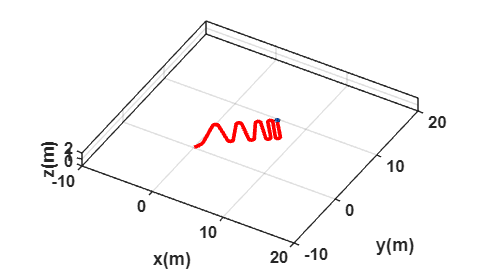

u =[  2*ones(1,5)   3*ones(1,5)   1*ones(1,5)     3*ones(1,5)  1*ones(1,5)   3*ones(1,5) 1*ones(1,5)   3*ones(1,5)    1*ones(1,5)   3*ones(1,5)   1*ones(1,5)   3*ones(1,5)  1*ones(1,5) 3*ones(1,5)  1*ones(1,5) 3*ones(1,5) 1*ones(1,5) 3*ones(1,6)];
w =[ 0.98*ones(1,5)  0*ones(1,5) -2.44*ones(1,5) 0*ones(1,5) 2.66*ones(1,5) 0*ones(1,5) -2.74*ones(1,5) 0*ones(1,5) 2.81*ones(1,5) 0*ones(1,5)  -2.9*ones(1,5) 0*ones(1,5) 3.06*ones(1,5) 0*ones(1,5) -3.16*ones(1,5) 0*ones(1,5) 3.16*ones(1,5) 0*ones(1,6)];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([30 30]); % Orientacion de la figura
axis([-10 20 -10 20 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

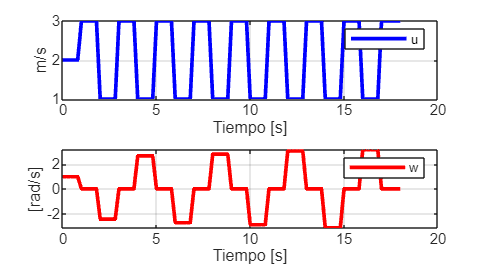


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');